# Occlusion Sensitivity

## Import GoogLeNet and read an image

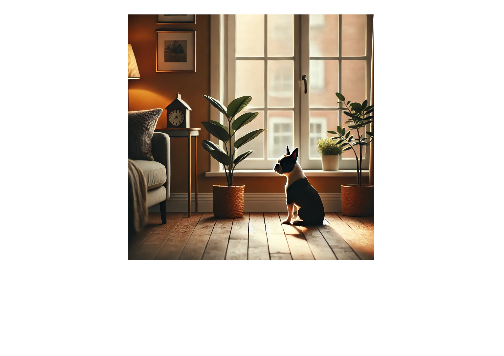

[net, classes] = imagePretrainedNetwork("googlenet");
img = imread("Boston bull2.jpg");
imshow(img)

## Resize the image for GoogLeNet

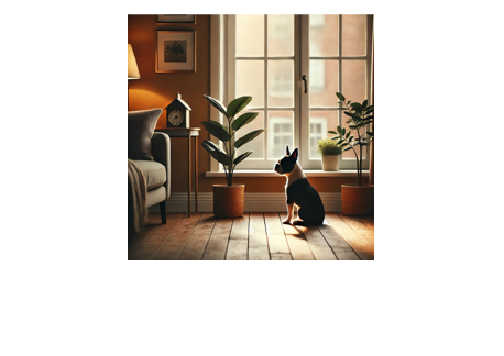

imgResized = imresize(img, [224 224]);
imshow(imgResized)

## Predict the image

scores = predict(net,single(imgResized));
[testPred, score] = scores2label(scores,classes);

## Calculate the occlusion sensitivity map

Use `occlusionSensitivity` to determine which parts of the image positively influence the classification result.

idx = find(string(testPred) == classes);
map = occlusionSensitivity(net,imgResized,idx);

## Overlay the sensitivity map

Plot the result over the original image with transparency to see which areas of the image affect the classification score.

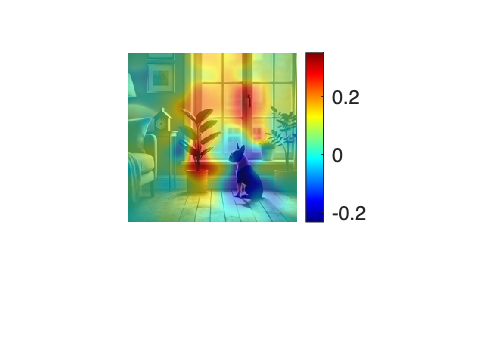

imshow(imgResized)
hold on
imagesc(map,"AlphaData",0.5) %The alpha value a is a number from 0 to 1, where 0 transparent and 1 is opaque.
hold off

colormap jet
colorbar